# **Correcting for Autocorrelation-induced Bias in Linear-dependence Measures**

## **with Applications to Functional Connectivity Analysis**

#### Software showcase for *CNS*2021 *by **Oliver Cliff **(University of Sydney)

Available: [https://github.com/olivercliff/exact-linear-dependence](https://github.com/olivercliff/exact-linear-dependence) 

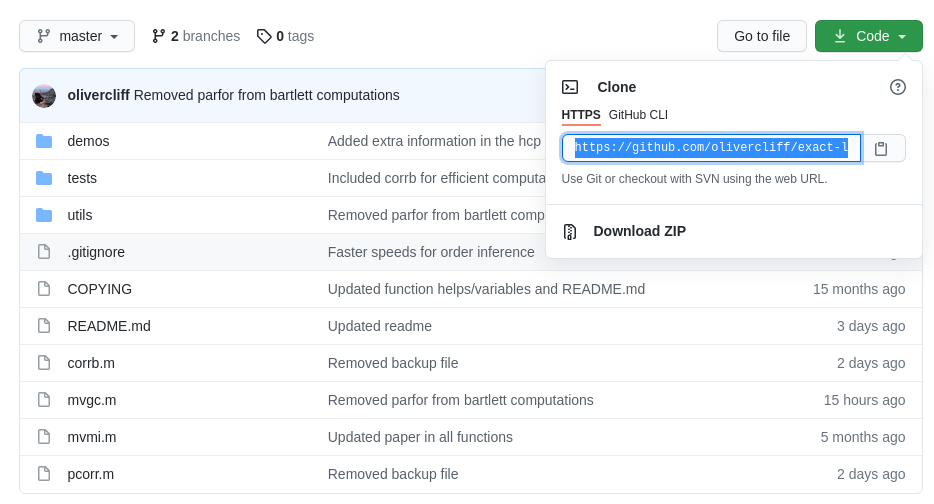

## Overview:

- Autocorrelation-induced bias in linear dependence measures for time series (synthetic and fMRI data).

- Brief introduction to the theory of modified hypothesis tests.

- Using our toolkit for the modified tests of **Pearson correlation**, **partial correlation**, **mutual information**, and **Granger causality **to univariate and multivariate time series.

- Constructing functional connectivity matrices and testing significant connections.

## Warm up for tutorial

Download the HCP data that we'll be using later on. This takes a while...

%#ok<*ASGLU>
clear

path = '~/Workspace/code/research/exact-linear-dependence';
cd(path) % Change directly to where we cloned the repository
cd demos % ...And into the demos folder

% Add all subdirectories
addpath(genpath(path))

% Download HCP resting-state data (for later)
downloadHCPData

Data file ./data/hcp_rsfMRI.mat exists.



% Seed RNG
rng(3);

## P-values and their distributions

First step, verify that everything makes sense for independent observations.

% Generate 256 observations from two independent standard Gaussians...
T = 2^8;
X = randn([T,1]);
Y = randn([T,1]);

% ...and plot them
figure;
subplot 211

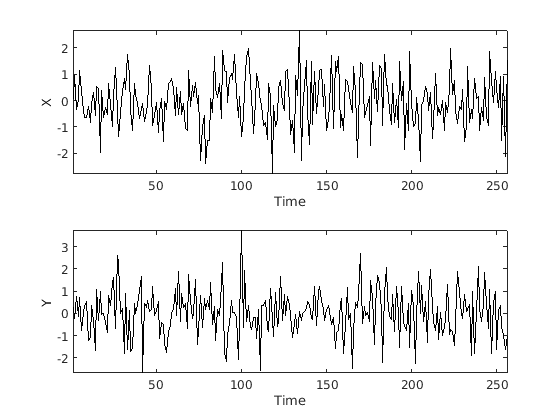

plot(X,'k'); xlabel('Time'); ylabel('X'); axis tight;
subplot 212
plot(Y,'k'); xlabel('Time'); ylabel('Y'); axis tight;


% Correlate the observations
[r,p] = corr(X,Y);
fprintf('Correlation between X and Y: %.3g (p-value of %.3g)', r, p);

Correlation between X and Y: -0.0413 (p-value of 0.511)

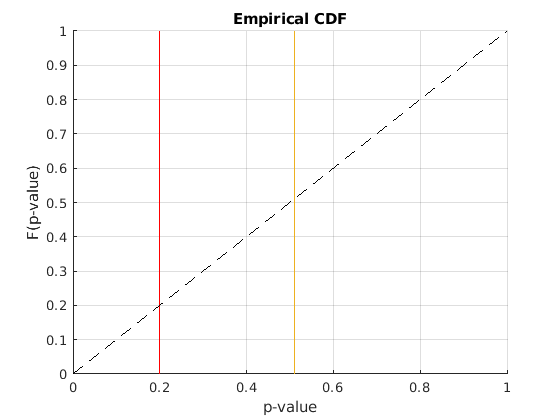


% Store our p-values
if ~exist('ps','var')
  ps = [];
end
ps = [ps;p];

% Statistical significance threshold (arbitrary choice)
alpha = 0.2;

% Show the CDF of the p-values
figure;
hold on;
plot([alpha,alpha],[0,1],'r-')
plot([0,1],[0,1],'k--')
cdfplot(ps);
xlabel('p-value'); ylabel('F(p-value)');
hold off;


fprintf('Proportion significant at p=%.1g: %.3g', alpha, mean(ps<=alpha));

Proportion significant at p=0.2: 0

## Lots of tests

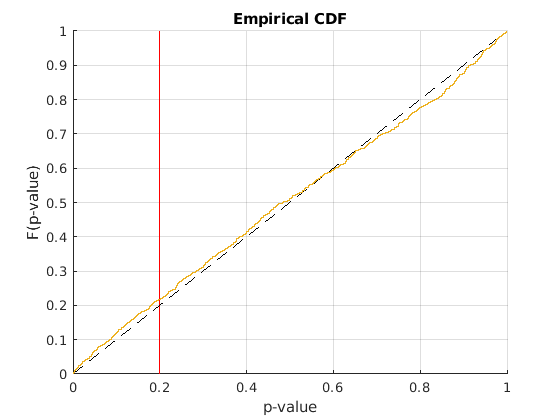

% Number of runs/experiments
R = 1000;
alpha = 0.2;

% Generate the processes
rs = zeros(R,1);
ps = zeros(R,1);
for r = 1:R
  X = randn([T,1]);
  Y = randn([T,1]);
  
  [rs(r),ps(r)] = corr(X,Y);
end

% Show the CDF of the p-values
figure;
hold on;
plot([alpha,alpha],[0,1],'r-')
plot([0,1],[0,1],'k--')
cdfplot(ps);
xlabel('p-value'); ylabel('F(p-value)');
grid on


significant_rs = ps <= alpha;

fprintf('Proportion of significant correlations at p = %.1g: %.2f%%', alpha, 100*mean( significant_rs ) );

Proportion of significant correlations at p = 0.2: 21.70%


ps = [];

## Hypothesis tests with AR(1) processes

Consider the two (independent) AR(1) processes:

#### 
$$\begin{array}{l}
X_t =\phi_X \;X_{t-1} +a_t \\
Y_t =\phi {\;}_Y Y_{t-1} +b_t 
\end{array}$$
 

where the innovations $a_t ,b_t \sim N\left(0,1\right)$ are normally distributed.

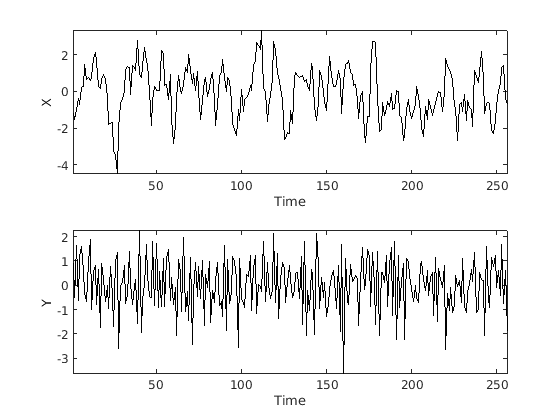

% Set up our parameters
phi_X = 0.7;
phi_Y = -0.5;
alpha = 0.2;

% Generate the processes
X = randn([T,1]);
Y = randn([T,1]);
for t = 2:T
  X(t) = phi_X * X(t-1) + X(t);
  Y(t) = phi_Y * Y(t-1) + Y(t);
end

% Plot the time series
figure;
subplot 211
plot(X,'k'); xlabel('Time'); ylabel('X'); axis tight;
subplot 212
plot(Y,'k'); xlabel('Time'); ylabel('Y'); axis tight;


[r,p] = corr(X,Y);
fprintf('Correlation between X and Y: %.3g (p-value of %.3g)', r, p);

Correlation between X and Y: -0.0668 (p-value of 0.287)

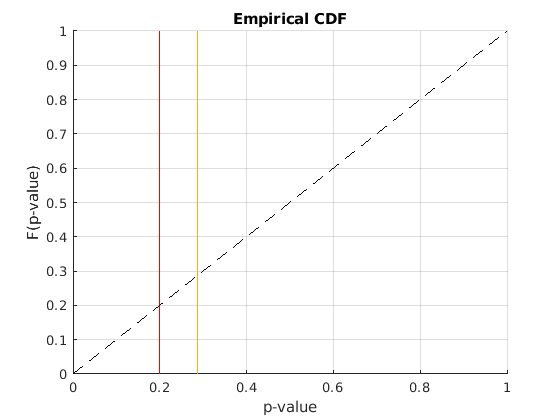


if ~exist('ps','var')
  ps = [];
end
ps = [ps;p];

figure;
hold on;
plot([alpha,alpha],[0,1],'r-')
plot([0,1],[0,1],'k--')
cdfplot(ps);
xlabel('p-value'); ylabel('F(p-value)');
hold off;


fprintf('Proportion significant at p = %.1g: %.3g', alpha, mean(ps<=alpha));

Proportion significant at p = 0.2: 0

## Lots of tests

In the null case, we expect 5% of the correlations to be significant at $p=0\ldotp 05$, so let's test this:

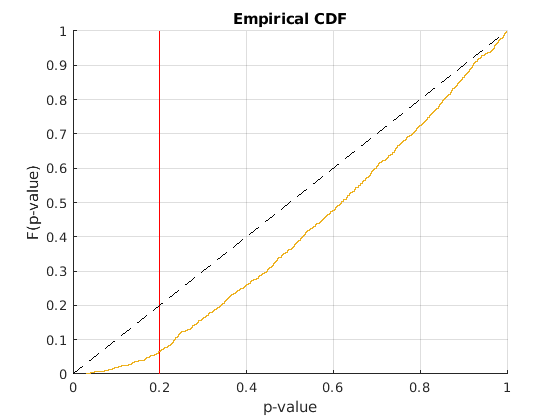

alpha = 0.2;

rs = zeros(R,1);
ps = zeros(R,1);
for r = 1:R
  X = randn([T,1]);
  Y = randn([T,1]);
  
  for t = 2:T
    X(t) = phi_X * X(t-1) + X(t);
    Y(t) = phi_Y * Y(t-1) + Y(t);
  end
  
  [rs(r),ps(r)] = corr(X,Y);
end

% Plot the distribution of p-values
figure;
hold on;
plot([alpha,alpha],[0,1],'r-')
% Versus the theoretically unbiased
plot([0,1],[0,1],'k--')
cdfplot(ps);
xlabel('p-value'); ylabel('F(p-value)');
grid on


significant_rs = ps <= alpha;

fprintf('Proportion of significant correlations at p = %.1f: %.2f%%', alpha, 100*mean( significant_rs ) );

Proportion of significant correlations at p = 0.2: 6.50%

## All linear-dependence measures are biased:

- (Pearson, partial and canonical) correlation

- Granger causality

- Mutual information

- Conditional mutual information

## A large amount of neuroscience data is autocorrelated:

- Naturally autocorrelated processes, e.g., haemodynamic response in fMRI.

- Autocorrelation through filtering (common to isolate 0.01 to 0.1 Hz for fMRI)

## Example: telepathy through brain signals

The Human Connectome Project resting-state data has the fMRI signals of hundreds of unrelated subjects imaged on different days at different times.

*Can we prove they have a telepathic connection through statistics?*

Let's load the data and find out...

load('./data/hcp_rsfMRI.mat','dat');

fprintf('Normalising and detrending...\n');

Normalising and detrending...


for i = 1:size(dat,3)
  s_bold = dat(:,:,i)';
  s_bold = detrend(s_bold);
  s_bold = zscore(s_bold);
  dat(:,:,i) = s_bold';
end

hcp_dat = dat(:,200:799,:);

[nregions,nobservations,nsubjects] = size(hcp_dat)

nregions = 333

nobservations = 600

nsubjects = 199

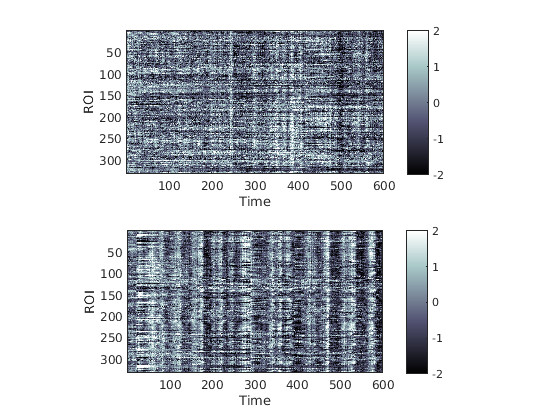


% Load, detrend and z-score the first two subjects from the HCP dataset
subject1_fmri = hcp_dat(:,:,1);
subject2_fmri = hcp_dat(:,:,2);

% Plot their carpet/raster plots
figure;
subplot 211
imagesc(subject1_fmri);
colormap('bone');
xlabel('Time');
ylabel('ROI');
caxis([-2,2]); axis equal; axis tight;
colorbar;

% Plot their carpet/raster plots
subplot 212
imagesc(subject2_fmri);
colormap('bone');
xlabel('Time');
ylabel('ROI');
caxis([-2,2]);  axis equal; axis tight;
colorbar;

## Correlation between subjects

How many significant connections are there between random regions of random subjects imaged at different times?

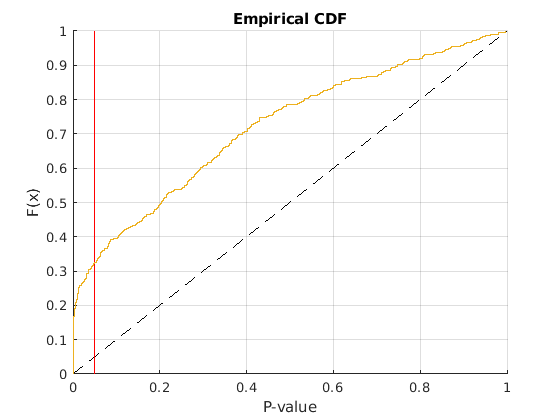

alpha = 0.05;

% Do a test for each ROI
R = size(subject1_fmri,1);
rs = zeros(R,1);
ps = zeros(R,1);
for r = 1:R
  subjects = randsample(nsubjects,2);
  regions = randsample(nregions,2);
  
  X = squeeze(hcp_dat(regions(1),:,subjects(1)))';
  Y = squeeze(hcp_dat(regions(2),:,subjects(2)))';
  
  [rs(r),ps(r)] = corr(X,Y);
end

% Plot the distribution of p-values
figure;
hold on;
% Versus the theoretically unbiased
plot([0,1],[0,1],'k--');
plot([alpha,alpha],[0,1],'r-');
cdfplot(ps);
xlabel('P-value');
grid on


significant_rs = ps <= alpha;

fprintf('Proportion of significant correlations at p = %.1g: %.2f%%', alpha, 100*mean( significant_rs ) );

Proportion of significant correlations at p = 0.05: 32.13%

### **Potential conclusions:**

- Our subjects are telepathic time travellers; or

- We've messed up the statistics.

## **Original (two-tailed) F-test for correlation:**

The original test we were using above is an F-test, which is commonly used for correlation analysis:

#### 
$$\left(T-2\right)\frac{{r_{\textrm{xy}} }^2 }{1-{r_{\textrm{xy}} }^2 }\sim F\left(1,T-2\right)$$


The p-value comes from the inverse CDF of the F-distribution:

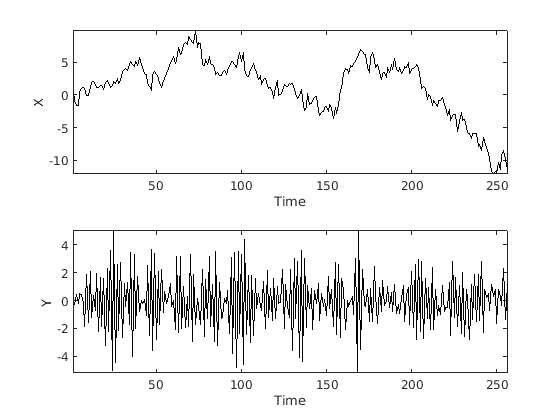

% Set up our parameters
phi_X = 0.95;
phi_Y = -0.9;

% Generate the processes
X = randn([T,1]);
Y = randn([T,1]);
for t = 2:T
  X(t) = phi_X * X(t-1) + X(t);
  Y(t) = phi_Y * Y(t-1) + Y(t);
end

% Plot the time series
figure;
subplot 211
plot(X,'k'); xlabel('Time'); ylabel('X'); axis tight;
subplot 212
plot(Y,'k'); xlabel('Time'); ylabel('Y'); axis tight;


% Compute the statistic
[r,p_inbuilt] = corr(X,Y);
p_inbuilt

p_inbuilt = 0.6056


% (Two-tailed) F-test
F = (T-2) * r^2 / (1-r^2);
p_F = 1-fcdf(F,1,T-2)

p_F = 0.6056

## **Bartlett's effective sample size:**

Bartlett showed that, when observations are correlated, we have a different number of samples than before.

This "effective sample size" can be computed from the autocorrelation function of the individual signals.

#### 
$$N_{\textrm{eff}} \approx \frac{T}{\sum_{t=1}^{T-1} \rho_{\textrm{XX}} \left(t\right)\;\rho_{\textrm{YY}} \left(t\right)}$$


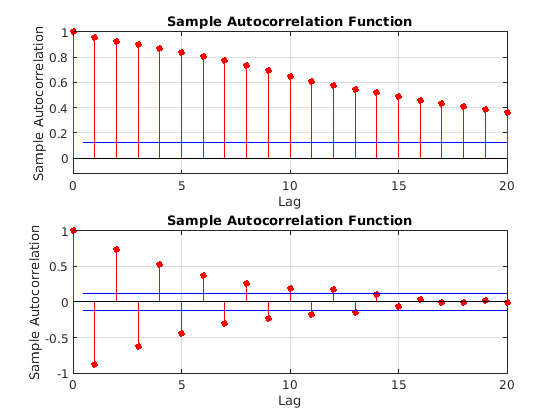

% Plot their autocorrelation
figure;
subplot 211
autocorr(X);
subplot 212
autocorr(Y);


r_XX = autocorr(X,T-1);
r_YY = autocorr(Y,T-1);

T

T = 256

N_eff = T / sum(r_XX.*r_YY)

N_eff = 471.4313

## **The modified hypothesis test**

Using the effective sample size, we get a modified hypothesis test:

#### 
$$\left(N_{\textrm{eff}} -2\right)\frac{{r_{\textrm{xy}} }^2 }{1-{r_{\textrm{xy}} }^2 }\sim F\left(1,N_{\textrm{eff}} -2\right)$$


How does this change the p-value?

t = r.*sqrt((N_eff-2)./(1-r.^2));
p_bartlett = 1-fcdf(t.^2,1,N_eff-2)

p_bartlett = 0.4825

### **Or, you can make your life easier and use our toolkit!**

We include some additional functionality to estimate the ACF (known as tapering), but the gist is the same.

% Add the directory (needs a few subfolders)
addpath(genpath('~/Workspace/code/research/exact-linear-dependence'));

[r,p_bartlett] = corrb(X,Y)

r = -0.0324

p_bartlett = 0.0748

Note that we only use the significant 

## Revisiting the first-order AR processes with modified F-tests

Let's revisit the issues we saw above with our modified hypothesis tests.

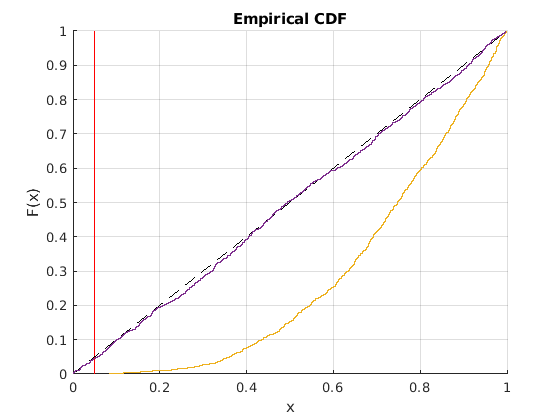

R = 1000;
phi_X = 0.8;
phi_Y = -0.8;
alpha = 0.05;

% Generate the processes
ps0 = zeros(R,1);
ps = zeros(R,1);
for r = 1:R
  X = randn([T,1]);
  Y = randn([T,1]);
  
  for t = 2:T
    X(t) = phi_X * X(t-1) + X(t);
    Y(t) = phi_Y * Y(t-1) + Y(t);
  end
  [~,ps0(r)] = corr(X,Y);
  [~,ps(r)] = corrb(X,Y);
end

% Plot the distribution of p-values
figure;
hold on;
plot([alpha,alpha],[0,1],'r-')
% Versus the theoretically unbiased
plot([0,1],[0,1],'k--')
cdfplot(ps0);
cdfplot(ps);
grid on


significant_rs0 = ps0 <= 0.05;
significant_rs = ps <= 0.05;

fprintf('[Original] Proportion of significant correlations at p = 0.05: %.3g%%', 100*mean( significant_rs0 ) );

[Original] Proportion of significant correlations at p = 0.05: 0%

fprintf('[Modified] Proportion of significant correlations at p = 0.05: %.3g%%', 100*mean( significant_rs ) );

[Modified] Proportion of significant correlations at p = 0.05: 4.5%

## Revisiting telepathy with modified F-tests

How many significant connections are there across two unrelated subjects imaged at different times?

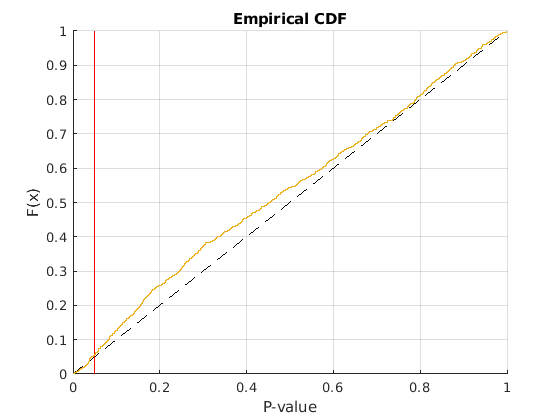

R = 1000;
alpha = 0.05;

% Do a test for each ROI
rs = zeros(R,1);
ps = zeros(R,1);

for r = 1:R
  % Randomly sample subjects and regions (without replacement) and..
  subjects = randsample(nsubjects,2);
  regions = randsample(nregions,2);
  
  X = squeeze(hcp_dat(regions(1),:,subjects(1)))';
  Y = squeeze(hcp_dat(regions(2),:,subjects(2)));
  [rs(r),ps(r)] = corrb(X,Y);
end

% Plot the distribution of p-values
figure;
hold on;
% Versus the theoretically unbiased
plot([0,1],[0,1],'k--');
plot([alpha,alpha],[0,1],'r-');
cdfplot(ps);
xlabel('P-value');
grid on


significant_rs = ps <= alpha;

fprintf('Proportion of significant correlations at p = %.1g: %.2f%%', alpha, 100*mean( significant_rs ) );

Proportion of significant correlations at p = 0.05: 5.70%

## All the linear dependence measures in our toolkit

In our paper, we introduced modified tests for **partial correlation**, **mutual information**, and **Granger causality**. These were derived by showing that linear-dependence measures can be expressed in terms of sums and products of partial correlation.

Modifying tests gets a bit involved for conditional measure (e.g., partial correlation) and multivariate measures (mutual information and Granger causality), so we've provided a toolkit.

The functions are in the familiar matlab format:

X = randn(T,1);
Y = randn(T,1);
W = randn(T,3);

% Pearson correlation
[r_XY,p] = corrb(X,Y)

r_XY = 0.0463

p = 0.4622


% Correlation matrices
[r_XY,p] = corrb([X,Y])

r_XY =     1.0000    0.0463
    0.0463    1.0000


p =          0    0.4622
    0.4622         0



% Partial correlation
[r_XY_W,p] = pcorr(X,Y,W)

r_XY_W = 0.0470

p = 0.4535


% Mutual information
[I_XY,p] = mvmi(X,Y)

I_XY = 0.0011

p = 0.5338


% Conditional mutual information
[I_XY_W,p] = mvmi(X,Y,W)

I_XY_W = 0.0011

p = 0.5508


% Granger causality
[F_XY,p] = mvgc(X,Y)

F_XY = 1.8390e-04

p = 0.1748


% Conditional Granger causality
[F_XY_W,p] = mvgc(X,Y,W)

F_XY_W = 1.5997e-04

p = 0.1626

## Modified tests for Pearson correlation

help corrb

  Pearson Correlation for vector AR processes.
    R = corrb(X,Y) returns the scalar estimate of the correlation
    between two vectors X and Y of equal length.
 
    R = corrb(X) returns the scalar estimate of the correlation
    between each pair of columns in the N-by-P matrix X.
 
    [R,PVAL] = corrb(...) also returns PVAL, the p-value for testing the
    hypothesis of no correlation
 
    [...] = corrb(...,'PARAM1',VAL1,'PARAM2',VAL2,...) specifies additional
    parameters and their values.  Valid parameters are the following:
 
          Parameter                   Value
           'test'                     'modified' (the default) uses our
                                      modified t-test,
                                      'finite' or 'asymptotic'
                                      uses the two-tailed t-test.
           'taperMethod'              'none' (default) to compute
                       

We've already seen how to compute 

The p-values can be computed from either our **modified tests** or the two-tailed **F-test.**

[r,p_modified] = corrb(X,Y)

r = 0.0463

p_modified = 0.4622

[r,p_finite] = corrb(X,Y,'test','finite')

r = 0.0463

p_finite = 0.4609

The hypothesis tests for Pearson correlation (and all measures) additionally can be computed with tapering of the autocorrelation function:

[~,p] = corrb(X,Y,'taperMethod','none')

p = 0.4622

[~,p_bartlett] = corrb(X,Y,'taperMethod','bartlett')

p_bartlett = 0.4623

[~,p_tukey] = corrb(X,Y,'taperMethod','tukey')

p_tukey = 0.4622

[~,p_parzen] = corrb(X,Y,'taperMethod','parzen')

p_parzen = 0.4625

## Modified tests for correlation matrices

Although the correlation matrix of a multivariate process can be computed by iterating through each pair, we recommend using the inbuilt functionality for efficiency (which caches the autocorrelation functions):

M = 20;
Z = randn(T,M);

Rs = zeros(M);
Ps = zeros(M);
tic;
for i = 1:M
  for j = i+1:M
    [Rr(i,j),Ps(i,j)] = corrb(Z(:,i),Z(:,j));
  end
end
Rs = Rs + Rs';
Ps = Ps + Ps';
toc

Elapsed time is 0.314280 seconds.



tic;
[Rs,Ps] = corrb(Z);
toc

Elapsed time is 0.017796 seconds.


## Modified tests for mutual information (univariate processes)

help mvmi

 mvmi Mutual information (conditional or unconditional) for vector AR processes.
    I = mvmi(X,Y) returns the scalar estimate of the linear-Gaussian
    Mutual information between the N-by-K matrix X and the N-by-L
    matrix Y. Columns of X and Y correspond to time series and rows
    correspond to time indices.
 
    I = mvmi(X,Y,W,...) returns the scalar estimate of linear-Gaussian
    Mutual information between X and Y conditioned on the N-by-C matrix W.
 
    [I,PVAL] = mvmi(...) also returns PVAL, the p-value for testing the
    hypothesis of no correlation
 
    [...] = mvmi(...,'PARAM1',VAL1,'PARAM2',VAL2,...) specifies additional
    parameters and their values.  Valid parameters are the following:
 
          Parameter                   Value
           'test'                     'modified' (the default) uses our
                                      modified lambda-test,
                   

Mutual information with a Gaussian estimator is equivalent to:

#### 
$$I\left(x;y\right)=-0\ldotp 5\;\log \left(1-{r_{\textrm{xy}} }^2 \right)$$


So we can easily compute this statistic in our toolkit, and give a convenient wrapper function for correlation analysis:

The p-values are computed from either our **modified tests, **finite-sample **F-tests, **or asymptotic **chi2 tests**.

[I_XY,p_modified] = mvmi(X,Y)

I_XY = 0.0011

p_modified = 0.5352

[I_XY,p_finite] = mvmi(X,Y,'test','finite')

I_XY = 0.0011

p_finite = 0.4598

[I_XY,p_asymptotic] = mvmi(X,Y,'test','asymptotic')

I_XY = 0.0011

p_asymptotic = 0.4587

Similarly, conditional mutual information is a function of partial correlation:

#### 
$$I\left(x;y\left|w\right.\right)=-0\ldotp 5\;\log \left(1-{r_{\textrm{xy}\cdot w} }^2 \right)$$


Again, this can be computed from our toolkit with ease:

[I_XY_W,p] = mvmi(X,Y,W)

I_XY_W = 0.0011

p = 0.5444

## Modified tests for mutual information (multivariate processes)

Mutual information for mutlivariate time series decomposes into sums of partial correlations:

#### $I\left(x;y\right)=-0\ldotp 5\;\sum_i \log \left(1-{r_i }^2 \right)$,

where each $r_i$ is a partial correlation (see our paper).

The p-values are computed from either our **modified tests **or asymptotic **chi2 tests:**

% Set up our parameters
T = 2^8;
M = 2;
phi_X = 0.8;
phi_Y = 0.8;

% Generate the processes
XM = randn([T,M]);
YM = randn([T,M]);
for t = 2:T
  XM(t) = phi_X .* XM(t-1) + XM(t);
  YM(t) = phi_Y .* YM(t-1) + YM(t);
end

[I_XY,p_modified] = mvmi(XM,YM) % Computed p-values from our modified F-tests

I_XY = 0.0011

p_modified = 0.0166

[I_XY,p_asymptotic] = mvmi(XM,YM,'test','asymptotic')

I_XY = 0.0011

p_asymptotic = 0.9684

Conditional mutual information is defined similarly, and computed from our toolkit by simply adding a third argument:

[I_XY_W,p] = mvmi(X,Y,W)

I_XY_W = 0.0011

p = 0.5586

## Modified tests for Granger causality (univariate processes)

help mvgc

 mvgc Multivariate Granger causality (conditional or unconditional).
    F = mvgc(X,Y) returns the scalar estimate of the Granger causality
    from the N-by-L matrix Y to the N-by-K matrix X. Columns of X and Y
    correspond to time series and rows correspond to time indices.
 
    F = mvgc(X,Y,W,...) returns the scalar estimate of Granger causality
    between X and Y conditioned on the N-by-C matrix W.
 
    [F,PVAL] = mvgc(...) also returns PVAL, the p-value for testing the
    hypothesis of no dependence
 
    [...] = mvgc(...,'PARAM1',VAL1,'PARAM2',VAL2,...) specifies additional
    parameters and their values.  Valid parameters are the following:
 
          Parameter                   Value
           'p'                        'auto' (the default) uses automatic
                                      embedding for the source process,
                                      otherwise input the de

Granger causality is a directed measurement of linear dependence. It is equivalent to a conditional mutual information:

#### 
$$F\left(x\to y\right)=2\cdot \;I\left(x_{t-p:t-1} ;y_t \left|y_{t-q:t-1} \right.\right)$$


There are a number of ways to infer the relevant history (p and q above).

We provide a method for **auto-embedding** using Burg's algorithm (similar to partial autocorrelation):

[F,p] = mvgc(X,Y) % Default is automatic selection of the AR order (p and q) from Burg's method.

F = 1.8390e-04

p = 0.1836

Optionally, you can **fix the embedding** of one or both of the time series:

[F,p] = mvgc(X,Y,'p','1') % Fix the embedding of the the source to 1 and auto-embed the target

F = 1.8390e-04

p = 0.1688

[F,p] = mvgc(X,Y,'p','1','q','10') % Fix the embedding of the the source to 1 and the target to 10

F = 0.0256

p = 0.1988

We provide tests for the **modified tests**, the finite-sample **F-tests**, and the **chi2 tests**:

[~,p_modified] = mvgc(X,Y) % modified test

p_modified = 0.1730

[~,p_modified] = mvgc(X,Y,'test','finite') % finite-sample F-test

p_modified = 0.8336

[~,p_modified] = mvgc(X,Y,'test','asymptotic') % asymptotic chi2-test

p_modified = 0.8286

## Modified tests for Granger causality (multivariate processes)

Multivariate Granger causality is treated similarly to univariate Granger causality above.

Again, we provide a method for **auto-embedding** using Burg's algorithm (similar to partial autocorrelation):

[F,p] = mvgc(XM,YM) % Default is automatic selection of the AR order (p and q) from Burg's method.

F = 0.0076

p = 0.0134

Optionally, you can **fix the embedding** of one or both of the time series:

[F,p] = mvgc(XM,YM,'p','1') % Fix the embedding of the the source to 1 and auto-embed the target

F = 0.0076

p = 0.0112

[F,p] = mvgc(XM,YM,'p','1','q','10') % Fix the embedding of the the source to 1 and the target to 10

F = 0.1667

p = 0.5140

We provide tests for the **modified tests**, the finite-sample **F-tests**, and the **chi2 tests**:

[~,p_modified] = mvgc(XM,YM) % modified test

p_modified = 0.0122

[~,p_modified] = mvgc(XM,YM,'test','finite') % finite-sample F-test

p_modified = 0.9850

[~,p_modified] = mvgc(XM,YM,'test','asymptotic') % asymptotic chi2-test

p_modified = 0.9832

## Case study: Testing the significance of functional connectivity matrices

% Pretty colormap installed w matlab
addpath /usr/local/MATLAB/R2020a/toolbox/bioinfo/microarray
cmap = redbluecmap(9);

[Rs,P0] = corr(subject1_fmri');

load('./data/id1plus.mat');

Error using load
'id1plus.mat' is not found in the current folder or on the MATLAB path, but exists in:
    /home/oliver/Dropbox/Workspace/code/sandbox/cns2021

Change the MATLAB current folder or add its folder to the MATLAB path.

M = size(subject1_fmri,1);
[~,order] = sort(id1plus(1:M));

figure;
imagesc(Rs(order,order),[-1,1]);
colormap(cmap);
colorbar;
xlabel('ROI'); ylabel('ROI'); axis square;
title('Correlation matrix');

% Bonferroni-corrected threshold
alpha = 0.05/M/(M-1);

R0 = Rs;
sig0 = P0 <= alpha;
R0(~sig0) = 0;

figure;
imagesc(R0(order,order),[-1,1]);
colormap(cmap);
colorbar;
xlabel('ROI'); ylabel('ROI'); axis square;
title('Correlation matrix with insignificant removed (F-test)');
fprintf('Density: %.2f%%', 100*mean(sig0(:)));

[~,PB] = corrb(subject1_fmri');
RB = Rs;
sigB = PB <= alpha;
RB(~sigB) = 0;

figure;
imagesc(RB(order,order),[-1,1]);
colormap(cmap);
colorbar;
xlabel('ROI'); ylabel('ROI'); axis square;
title('Correlation matrix with insignificant removed (modified F-test)');
fprintf('Modified density: %.2f%%', 100*mean(sigB(:)));